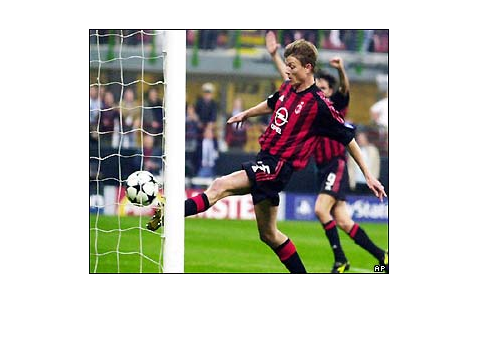

clear all
image=imread('05.jpg');
image=double(image);
figure,imshow(uint8(image))


Image_red = image(:,:,1);
Image_green = image(:,:,2);
Image_blue = image(:,:,3);

[row,col] = size(image(:,:,1));

imageSize = row * col

imageSize = 73500



row = row/4

row = 61.2500

col = col/4

col = 75


startrow = uint32(row*3)

startrow = uint32
184

startcol = uint32(col*1)

startcol = uint32
75


endrow = uint32(row*4)

endrow = uint32
245

endcol = uint32(col*2)

endcol = uint32
150

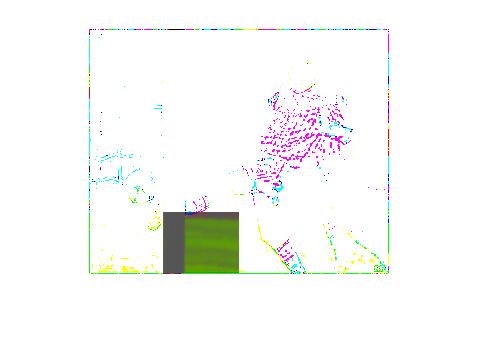


redPixels = 0;
bluePixels = 0;

for y = startrow:endrow 
    for x = startcol:endcol 
      Red = Image_red(y,x);
      Green = Image_green(y,x);
      Blue = Image_blue(y,x);
      
      if (Red >= 125 && Red <= 175)
          redPixels = redPixels + 1;
      end
      
      if (Blue >= 40 && Blue <= 80)
          bluePixels = bluePixels + 1;
      end
    
      NormalizedRed = Red/(Red + Green + Blue);
      NormalizedGreen = Green/(Red + Green + Blue);
      NormalizedBlue = Blue/(Red + Green + Blue);
    
      Image_red(y,x) = NormalizedRed;
      Image_green(y,x) = NormalizedGreen;
      Image_blue(y,x) = NormalizedBlue;
    end
end
image(:,:,1) = Image_red;
image(:,:,2) = Image_green;
image(:,:,3) = Image_blue;

figure; imshow(uint8(255*image));

redPixels

redPixels = 945

bluePixels

bluePixels = 1108

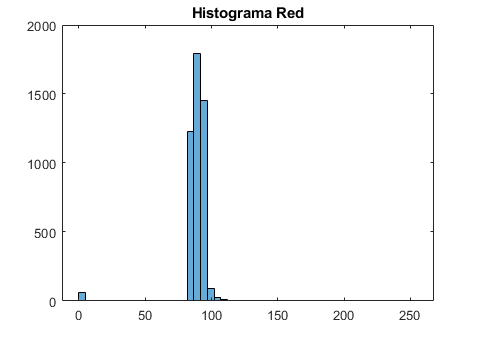


% histogram(image, nBins)
histogram(Image_red(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Red')

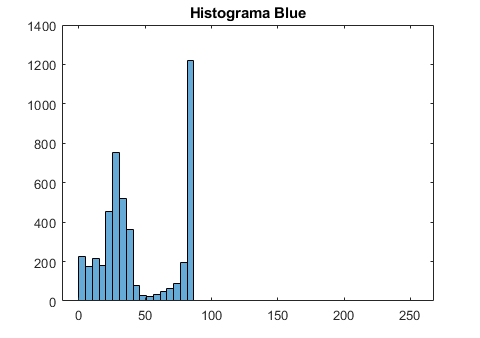

histogram(Image_blue(startrow:endrow,startcol:endcol)*255,50), title('Histograma Blue')

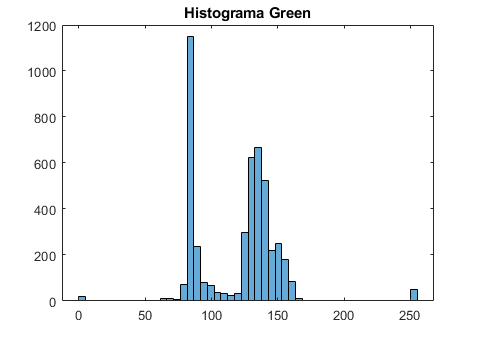

histogram(Image_green(startrow:endrow,startcol:endcol)*255,50), title('Histograma Green')